clear
clc

# FASE DE ENTRENAMIENTO

## CARGA DE DATOS DE ENTRENAMIENTO

nombre_archivo_excel = 'Datos_Operadores_Entrenamiento.xlsx';
datos = readtable(nombre_archivo_excel);

disp('Primeras filas del dataset:');

Primeras filas del dataset:


disp(datos(1:5,:));

    TiempoCiclo    Defectos    HorasExperiencia    Variabilidad      Nivel   
    ___________    ________    ________________    ____________    __________

        128           5               58                 9         {'Novato'}
        148           8               41                 8         {'Novato'}
         86           4               51                 8         {'Novato'}
        133           5               45                 6         {'Novato'}
        125           8               53                10         {'Novato'}



## SEPARACIÓN DE VARIABLES

Columnas: 

- [1] Tiempo Ciclo (TC): Tiempo que tarda el trabajador

- [2] Defectos: Número de defector cometidos en la elaboración de ese ciclo

- [3] Horas Experiencia (HE): Categoría del empleado según su experiencia 

- [4] Variabilidad: Variabilidad respecto al Tiempo Ciclo

X = datos{:, 1:4};
Y = datos{:, 5};          % Etiquetas: Novato / Estándar / Experto
labels = unique(Y);        % Orden alfabético (Estándar, Experto, Novato)

% Medias de entrenamiento(fallback para imputación)
col_means = mean(X, 'omitnan'); 
% omitnan ingonra nulos para no afectar el promedio

Nota:

Como nota podemos decir, que se pudo sacar los valores de algúnas columnas por medio de los promedios y ahorrarnos crear el modelo de regresión, en por ejenmplo el tiempo promedio de un empleado por su categoría.

Pero por fines educativos y de práctica, crearé un modelo de regresión, para la predicción de cada columna, apartir de columnas con datos ya existentes, para apartir de ello hacer predicciones.

## MODELOS DE REGRESIÓN PARA IMPUTACIÓN

mdl_tiempo = fitrlinear(X(:,[2 3 4]), X(:,1)); % predice col 1 apartir de Defectos,HE y variabilidad
mdl_defectos = fitrlinear(X(:,[1 3 4]), X(:,2)); % predice col 2 apartir de TC,HE y variabilidad
mdl_experiencia = fitrlinear(X(:,[1 2 4]), X(:,3)); % predice col 3 apartir de TC, Defectos y variabilidad
mdl_variabilidad = fitrlinear(X(:,[1 2 3]), X(:,4)); % predice col 4 apartir de TC, Defectos y HE

disp('Modelos de regresión (imputación) entrenados.');

Modelos de regresión (imputación) entrenados.


## ENTRENAMIENTO DE 3 CLASIFICADORES NAIVE BAYES

Se entrenará y posteriormente se graficará respecto a 2 variables (un par), usando el modelo Naive Bayes, para analizar y visualizar mejor una relación, por el tipo de problema y la posible relación que estimó que tienen los datos respecto a su dependencía entre ellos. Los pares formados son lo siguientes

- Par TD : Tiempo Ciclo + Número de Defectos (cols 1-2) 

- Par TE : Tiempo Ciclo + Horas de Experiencia (cols 1-3) 

- Par DE : Número de Defectos + Horas de Experiencia (cols 2-3)

mdl_NB_TD = fitcnb(X(:,[1 2]), Y);
mdl_NB_TE = fitcnb(X(:,[1 3]), Y);
mdl_NB_DE = fitcnb(X(:,[2 3]), Y);

disp('Clasificadores Naive Bayes entrenados (3 pares de variables).');

Clasificadores Naive Bayes entrenados (3 pares de variables).


## PRE-CÁLCULO DE SUPERFICIES DE DECISIÓN (malla 2D)

% Par TD 
[xx1_TD, xx2_TD] = meshgrid( linspace(min(X(:,1)), max(X(:,1)), 200), ...
                              linspace(min(X(:,2)), max(X(:,2)), 200) );
XGrid_TD = [xx1_TD(:), xx2_TD(:)];
[pred_TD, Post_TD] = predict(mdl_NB_TD, XGrid_TD);
sz_TD = size(xx1_TD);

% Par TE 
[xx1_TE, xx2_TE] = meshgrid( linspace(min(X(:,1)), max(X(:,1)), 200), ...
                              linspace(min(X(:,3)), max(X(:,3)), 200) );
XGrid_TE = [xx1_TE(:), xx2_TE(:)];
[pred_TE, Post_TE] = predict(mdl_NB_TE, XGrid_TE);
sz_TE = size(xx1_TE);

% Par DE
[xx1_DE, xx2_DE] = meshgrid( linspace(min(X(:,2)), max(X(:,2)), 200), ...
                              linspace(min(X(:,3)), max(X(:,3)), 200) );
XGrid_DE = [xx1_DE(:), xx2_DE(:)];
[pred_DE, Post_DE] = predict(mdl_NB_DE, XGrid_DE);
sz_DE = size(xx1_DE);

disp('Superficies de decisión calculadas para los 3 pares.');

Superficies de decisión calculadas para los 3 pares.


# FASE DE ENTRENAMIENTO

## CARGA DE DATOS DE NUEVOS OPERADORES PARA PROBAR

datos_nuevos = readtable('Datos_Operadores_Nuevos.xlsx');
X_new_original = datos_nuevos{:, 1:4};   % Puede contener NaN
X_new_completo = X_new_original;          % Copia que se completará

disp('Datos originales de nuevos operadores (NaN = valor faltante):');

Datos originales de nuevos operadores (NaN = valor faltante):


disp(X_new_original);

   128     4    37     8
   148     7    80     8
   NaN     9    57   NaN
   NaN    19    49   NaN
   NaN    16    57   NaN
   NaN     6   227   NaN
    85     5   166     3
   101     3   168     2
   NaN     5   176   NaN
    99     2   112     1
    69   NaN   457     2
    69   NaN   504     1
    72   NaN   439     2
    72   NaN   444     1
    66   NaN   500     2



## CLASIFICACIÓN DE LOS NUEVOS OPERADORES A CLASIFICAR (15 EN ESTE CASO)

% Vectores para almacenar resultados
etiquetas_finales = cell(15,1);
probabilidades_finales = zeros(15,1);
variables_usadas = cell(15,1);

for i = 1:size(X_new_original, 1)
    fprintf('OPERADOR %d\n', i);

    fila_original = X_new_original(i, :);   % guarda el estado ANTES de imputar
    fila = fila_original;

    % IMPUTACIÓN según el campño faltante
    % Se repite 4 veces para resolver dependencias en cascada
    % (ej.: si Tiempo y Defectos son NaN al mismo tiempo) y poder usar el modelo correspondiente
    for pase = 1:4
        if isnan(fila(1)) && ~any(isnan(fila([2 3 4])))
            fila(1) = predict(mdl_tiempo, fila([2 3 4]));
        end
        if isnan(fila(2)) && ~any(isnan(fila([1 3 4])))
            fila(2) = predict(mdl_defectos, fila([1 3 4]));
        end
        if isnan(fila(3)) && ~any(isnan(fila([1 2 4])))
            fila(3) = predict(mdl_experiencia, fila([1 2 4]));
        end
        if isnan(fila(4)) && ~any(isnan(fila([1 2 3])))
            fila(4) = predict(mdl_variabilidad, fila([1 2 3]));
        end
    end

    % Último recurso, si aún hay NaN, usar la media del entrenamiento,
    % solución comentada en la nota de la 3ra celda como último recurso
    for k = 1:4
        if isnan(fila(k))
            fila(k) = col_means(k);
        end
    end

    X_new_completo(i,:) = fila;

    % SELECCIÓN DEL PAR de variables a gráficar
    % Se da prioridad al par cuyas DOS variables estaban originalmente disponibles (no eran NaN)
    disp_orig = ~isnan(fila_original);

    if disp_orig(1) && disp_orig(2)          % Tiempo Y Defectos disponibles
        par = 'TD';
    elseif disp_orig(1) && disp_orig(3)      % Tiempo Y Experiencia disponibles
        par = 'TE';
    elseif disp_orig(2) && disp_orig(3)      % Defectos Y Experiencia disponibles
        par = 'DE';
    else
        par = 'TD';   % Fallback: se usa TD con valores imputados
    end

OPERADOR 1


OPERADOR 2


OPERADOR 3


OPERADOR 4


OPERADOR 5


OPERADOR 6


OPERADOR 7


OPERADOR 8


OPERADOR 9


OPERADOR 10


OPERADOR 11


OPERADOR 12


OPERADOR 13


OPERADOR 14


OPERADOR 15


## ASIGNACIÓN DE RECURSOS SEGÚN EL PAR ELEGIDO

    switch par
        case 'TD'
            X_input = fila([1 2]);
            lbl1 ='Tiempo Ciclo';
            lbl2 ='Número de Defectos';
            xx1_u = xx1_TD;  xx2_u = xx2_TD;
            pred_u = pred_TD; Post_u = Post_TD; sz_u = sz_TD;

        case 'TE'
            X_input = fila([1 3]);
            lbl1 = 'Tiempo Ciclo';
            lbl2 = 'Horas de Experiencia';
            xx1_u = xx1_TE;  xx2_u = xx2_TE;
            pred_u = pred_TE; Post_u = Post_TE; sz_u = sz_TE;

        case 'DE'
            X_input = fila([2 3]);
            lbl1 = 'Número de Defectos';
            lbl2 = 'Horas de Experiencia';
            xx1_u = xx1_DE;  xx2_u = xx2_DE;
            pred_u = pred_DE; Post_u = Post_DE; sz_u = sz_DE;
    end

## CLASIFICACIÓN

    [etiqueta_predicha, probabilidad] = predict( ...
        eval(['mdl_NB_' par]), X_input);
    valor_probabilidad = max(probabilidad);

    etiquetas_finales{i} = etiqueta_predicha{1};
    probabilidades_finales(i) = valor_probabilidad;
    variables_usadas{i} = [lbl1 ' + ' lbl2];


## GRAFICACIÓN

Se grafícara con el objetivo d evisualizar en que zona de clasificación caé cada punto, tanto en 2D y 3D para mayor precisión y en diversas perspectivas se puede ver más claro. Además, se irán cambiando los campos que se usarán como ejes, buscando una posible relación o patrón vista de manera más notorio lás zonas de clasificación de los clusters.

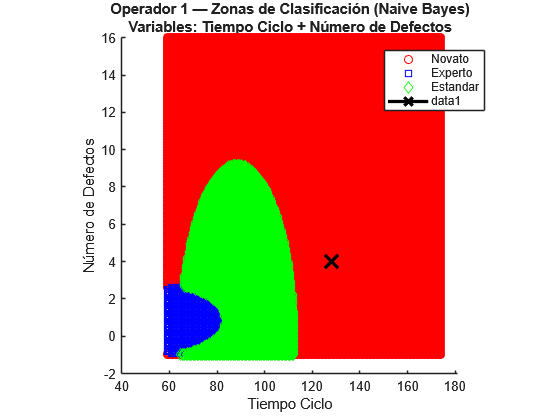

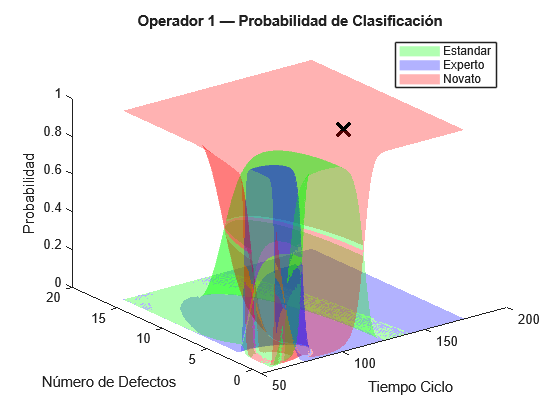


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Tiempo Ciclo + Número de Defectos


Valor Variable 1 (Tiempo Ciclo) : 128


Valor Variable 2 (Número de Defectos): 4


Clasificación predicha  : **Novato**


Probabilidad asociada   : 0.999843


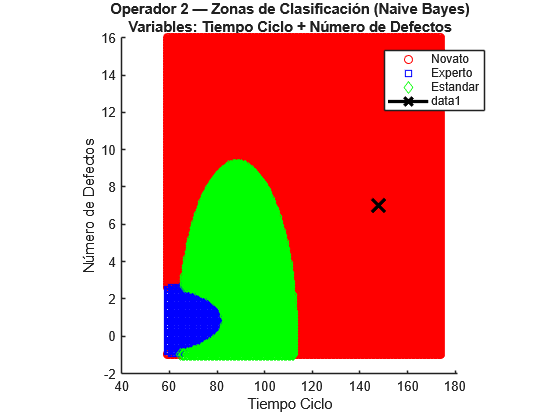

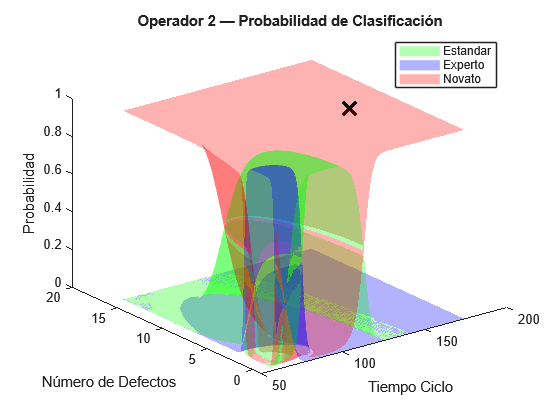


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Tiempo Ciclo + Número de Defectos


Valor Variable 1 (Tiempo Ciclo) : 148


Valor Variable 2 (Número de Defectos): 7


Clasificación predicha  : **Novato**


Probabilidad asociada   : 1


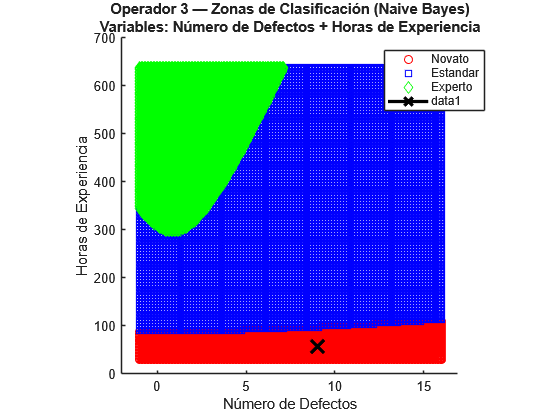

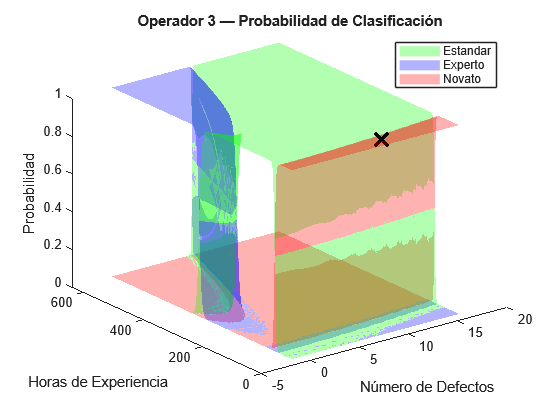


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Número de Defectos + Horas de Experiencia


Valor Variable 1 (Número de Defectos) : 9


Valor Variable 2 (Horas de Experiencia): 57


Clasificación predicha  : **Novato**


Probabilidad asociada   : 1


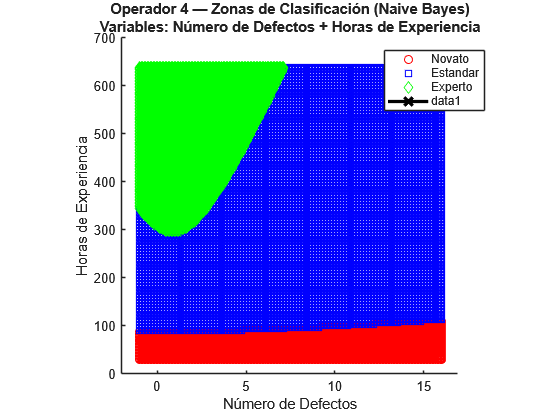

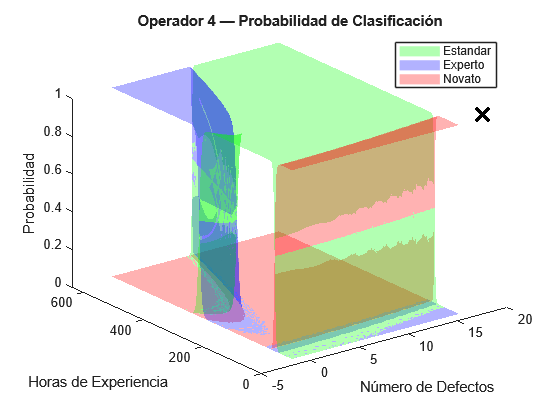


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Número de Defectos + Horas de Experiencia


Valor Variable 1 (Número de Defectos) : 19


Valor Variable 2 (Horas de Experiencia): 49


Clasificación predicha  : **Novato**


Probabilidad asociada   : 1


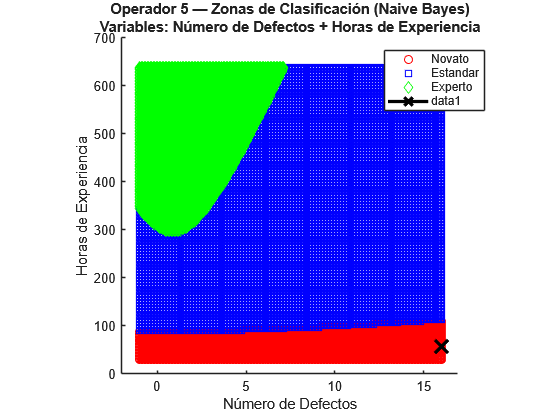

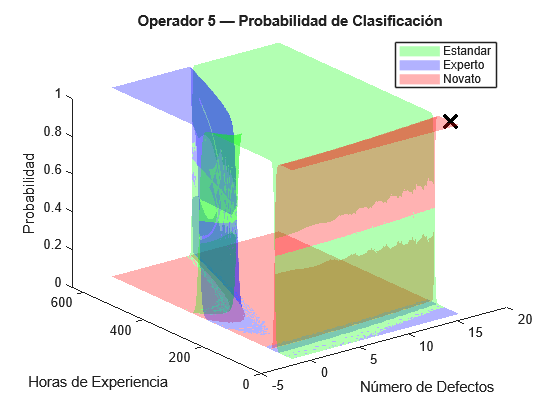


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Número de Defectos + Horas de Experiencia


Valor Variable 1 (Número de Defectos) : 16


Valor Variable 2 (Horas de Experiencia): 57


Clasificación predicha  : **Novato**


Probabilidad asociada   : 1


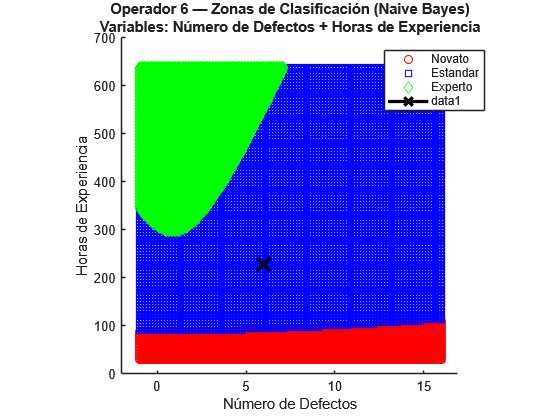

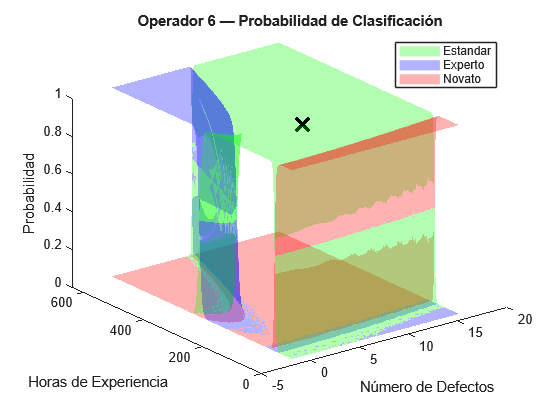


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Número de Defectos + Horas de Experiencia


Valor Variable 1 (Número de Defectos) : 6


Valor Variable 2 (Horas de Experiencia): 227


Clasificación predicha  : **Estandar**


Probabilidad asociada   : 1


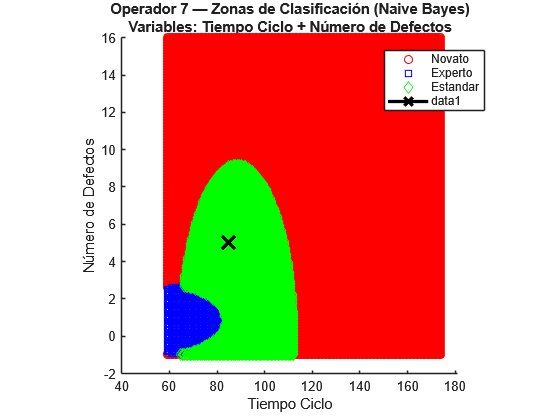

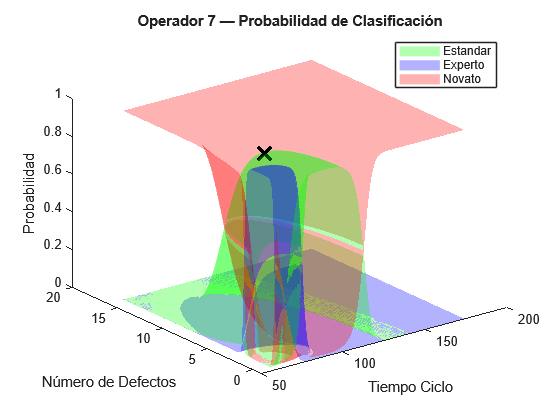


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Tiempo Ciclo + Número de Defectos


Valor Variable 1 (Tiempo Ciclo) : 85


Valor Variable 2 (Número de Defectos): 5


Clasificación predicha  : **Estandar**


Probabilidad asociada   : 0.952592


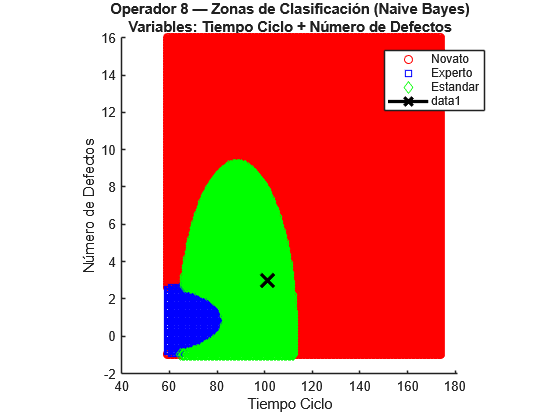

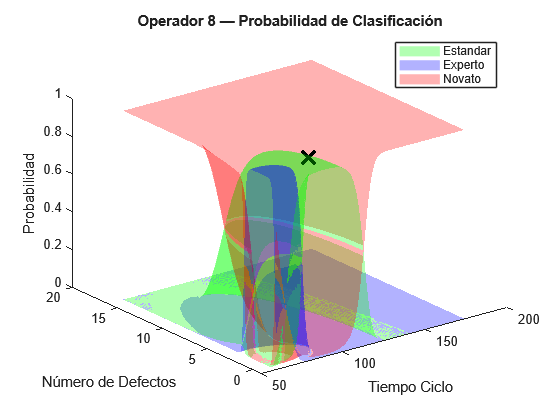


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Tiempo Ciclo + Número de Defectos


Valor Variable 1 (Tiempo Ciclo) : 101


Valor Variable 2 (Número de Defectos): 3


Clasificación predicha  : **Estandar**


Probabilidad asociada   : 0.940211


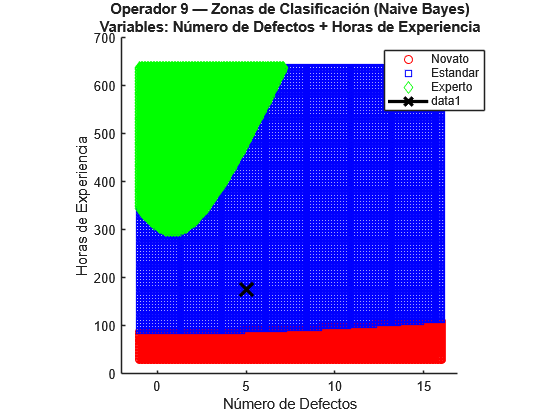

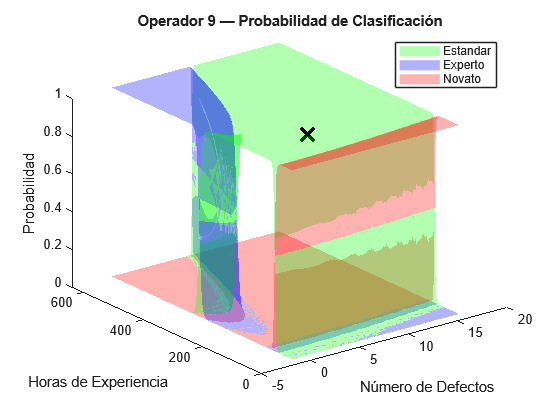


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Número de Defectos + Horas de Experiencia


Valor Variable 1 (Número de Defectos) : 5


Valor Variable 2 (Horas de Experiencia): 176


Clasificación predicha  : **Estandar**


Probabilidad asociada   : 1


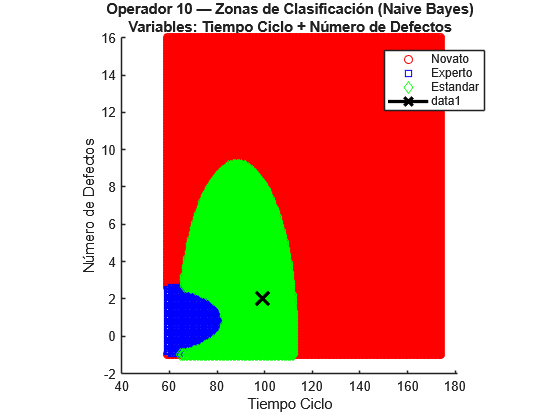

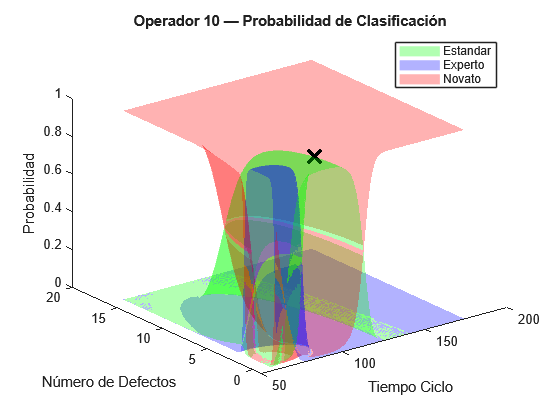


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Tiempo Ciclo + Número de Defectos


Valor Variable 1 (Tiempo Ciclo) : 99


Valor Variable 2 (Número de Defectos): 2


Clasificación predicha  : **Estandar**


Probabilidad asociada   : 0.96805


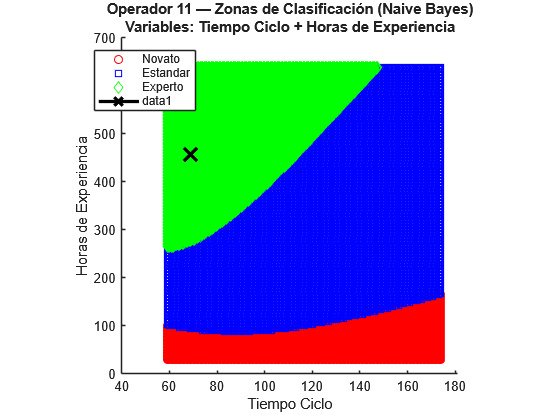

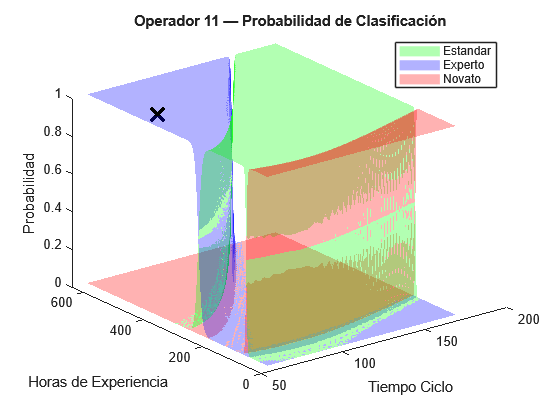


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Tiempo Ciclo + Horas de Experiencia


Valor Variable 1 (Tiempo Ciclo) : 69


Valor Variable 2 (Horas de Experiencia): 457


Clasificación predicha  : **Experto**


Probabilidad asociada   : 1


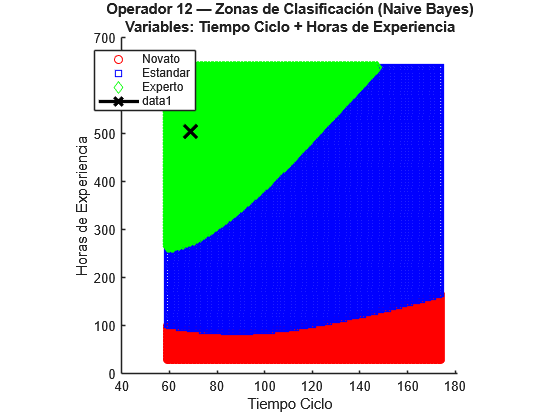

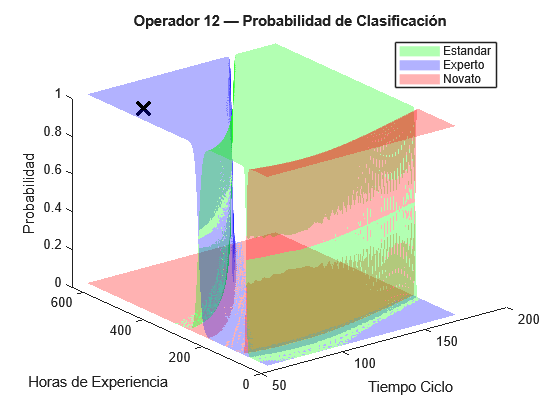


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Tiempo Ciclo + Horas de Experiencia


Valor Variable 1 (Tiempo Ciclo) : 69


Valor Variable 2 (Horas de Experiencia): 504


Clasificación predicha  : **Experto**


Probabilidad asociada   : 1


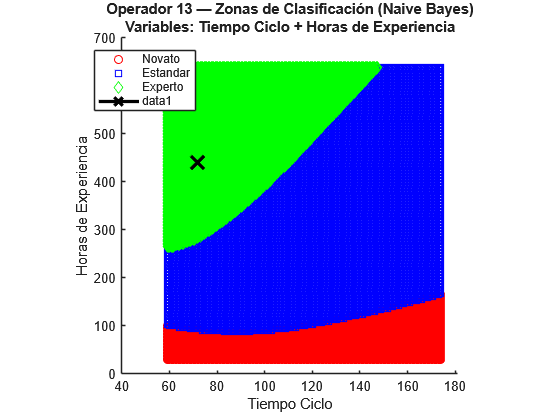

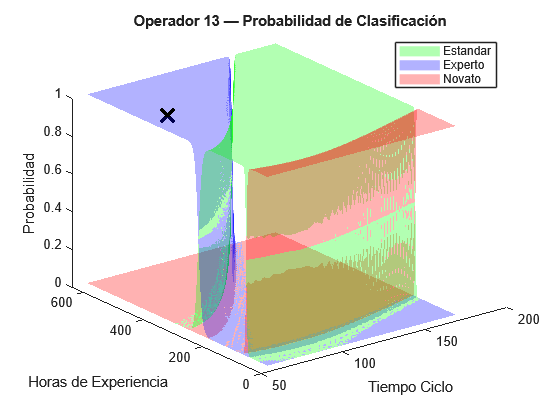


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Tiempo Ciclo + Horas de Experiencia


Valor Variable 1 (Tiempo Ciclo) : 72


Valor Variable 2 (Horas de Experiencia): 439


Clasificación predicha  : **Experto**


Probabilidad asociada   : 1


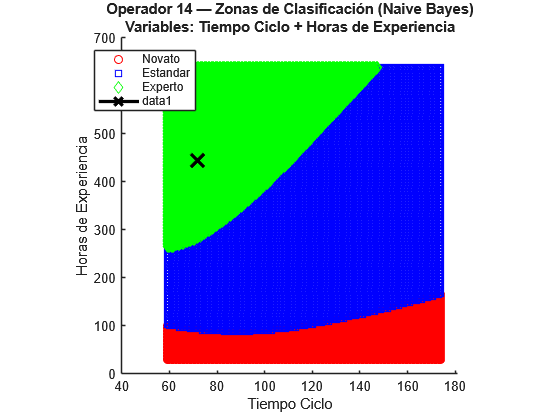

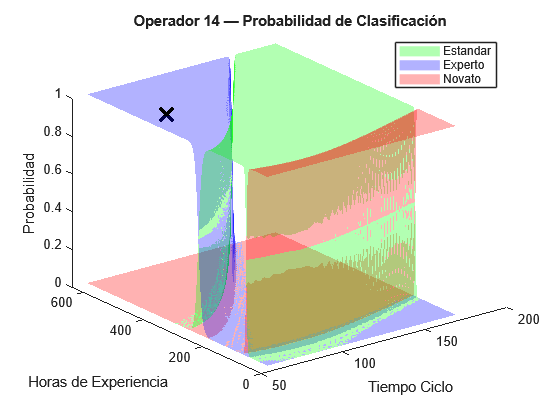


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Tiempo Ciclo + Horas de Experiencia


Valor Variable 1 (Tiempo Ciclo) : 72


Valor Variable 2 (Horas de Experiencia): 444


Clasificación predicha  : **Experto**


Probabilidad asociada   : 1


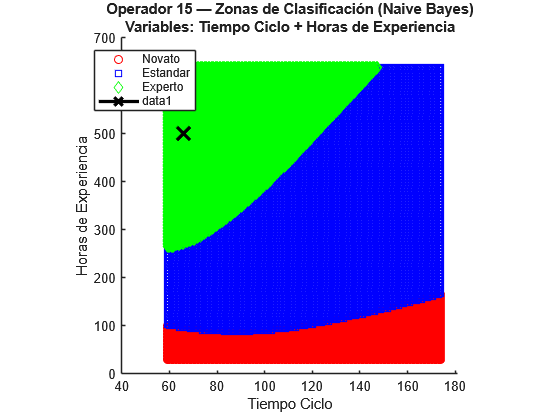

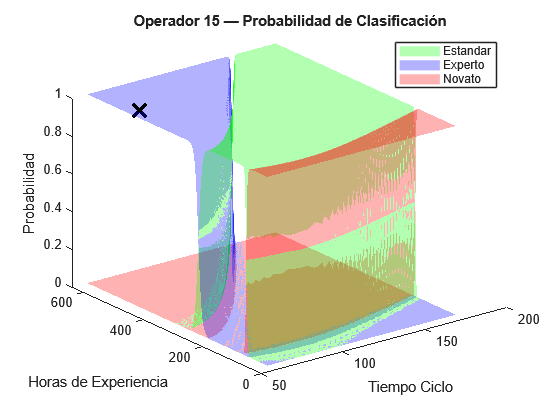


RESULTADO DE LA CLASIFICACIÓN


Variables usadas        : Tiempo Ciclo + Horas de Experiencia


Valor Variable 1 (Tiempo Ciclo) : 66


Valor Variable 2 (Horas de Experiencia): 500


Clasificación predicha  : **Experto**


Probabilidad asociada   : 1


    % GRÁFICA 2D
    figure;
    gscatter(xx1_u(:), xx2_u(:), pred_u, 'rbg', 'osd');
    hold on
    line(X_input(1), X_input(2), ...
        'Marker','x', 'Color','k', 'MarkerSize',14, 'LineWidth',2.5);
    xlabel(lbl1);
    ylabel(lbl2);
    title(sprintf('Operador %d — Zonas de Clasificación (Naive Bayes)\nVariables: %s + %s', ...
        i, lbl1, lbl2));
    axis square;
    hold off

    % GRÁFICA 3D 
    figure;
    hold on
    surf(xx1_u, xx2_u, reshape(Post_u(:,1), sz_u), ...
        'FaceColor','green', 'EdgeColor','none')
    surf(xx1_u, xx2_u, reshape(Post_u(:,2), sz_u), ...
        'FaceColor','blue',  'EdgeColor','none')
    surf(xx1_u, xx2_u, reshape(Post_u(:,3), sz_u), ...
        'FaceColor','red',   'EdgeColor','none')
    line(X_input(1), X_input(2), valor_probabilidad, ...
        'Marker','x', 'Color','k', 'MarkerSize',14, 'LineWidth',2.5);
    xlabel(lbl1);
    ylabel(lbl2);
    zlabel('Probabilidad');
    legend(labels);
    title(sprintf('Operador %d — Probabilidad de Clasificación', i));
    alpha(0.3);
    view(3);
    hold off

    % RESULTADO DE LA CLASIFICACIÓN
    
    disp([newline 'RESULTADO DE LA CLASIFICACIÓN']);
    fprintf('Variables usadas        : %s\n', variables_usadas{i});
    fprintf('Valor Variable 1 (%s) : %g\n', lbl1, X_input(1));
    fprintf('Valor Variable 2 (%s): %g\n', lbl2, X_input(2));
    fprintf('Clasificación predicha  : **%s**\n', etiqueta_predicha{1});
    fprintf('Probabilidad asociada   : %g\n', valor_probabilidad);
    disp(' ');
end

## RESUMEN FINAL EN TABLA

disp(' ');


disp('RESUMEN FINAL DE LOS NUEVOS OPERADORES');

RESUMEN FINAL DE LOS NUEVOS OPERADORES



fprintf('%-4s  %-38s  %-12s  %-12s\n', ...
    '', 'Variables Usadas', 'Clasificación', 'Probabilidad');

      Variables Usadas                        Clasificación  Probabilidad


fprintf('%s\n', repmat('-', 1, 80));

------------------------------------------------------------------------


for i = 1:15
    fprintf('%-4d  %-38s  %-12s  %.5f\n', ...
        i, variables_usadas{i}, etiquetas_finales{i}, probabilidades_finales(i));
end

1     Tiempo Ciclo + Número de Defectos       Novato        0.99984
2     Tiempo Ciclo + Número de Defectos       Novato        1.00000
3     Número de Defectos + Horas de Experiencia  Novato        1.00000
4     Número de Defectos + Horas de Experiencia  Novato        1.00000
5     Número de Defectos + Horas de Experiencia  Novato        1.00000
6     Número de Defectos + Horas de Experiencia  Estandar      1.00000
7     Tiempo Ciclo + Número de Defectos       Estandar      0.95259
8     Tiempo Ciclo + Número de Defectos       Estandar      0.94021
9     Número de Defectos + Horas de Experiencia  Estandar      1.00000
10    Tiempo Ciclo + Número de Defectos       Estandar      0.96805
11    Tiempo Ciclo + Horas de Experiencia     Experto       1.00000
12    Tiempo Ciclo + Horas de Experiencia     Experto       1.00000
13    Tiempo Ciclo + Horas de Experiencia     Experto       1.00000
14    Tiempo Ciclo + Horas de Experiencia     Experto       1.00000
15    Tiempo Ciclo + Horas de Exp

## GUARDAR MODELOS

save('modelo_operadores.mat', ...
    'mdl_NB_TD', 'mdl_NB_TE', 'mdl_NB_DE', ...
    'mdl_tiempo', 'mdl_defectos', 'mdl_experiencia', 'mdl_variabilidad');

disp(' ');

disp('Modelos guardados en modelo_operadores.mat');

Modelos guardados en modelo_operadores.mat


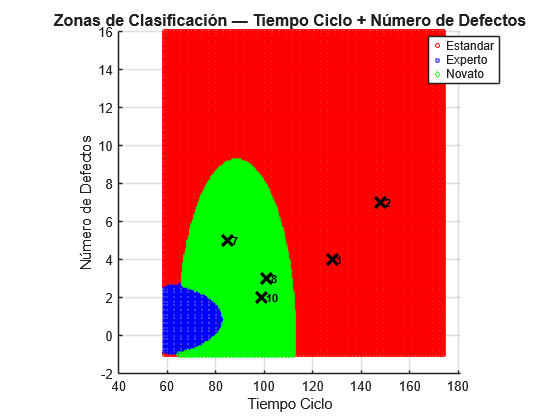

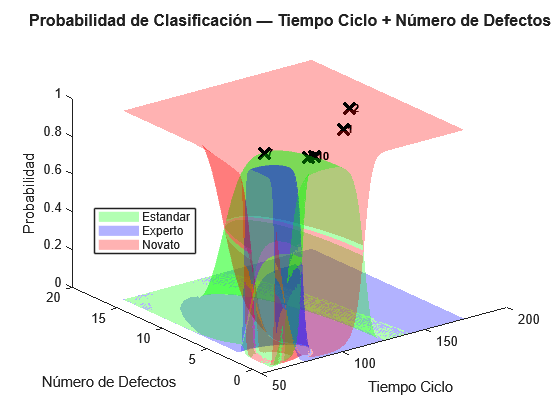

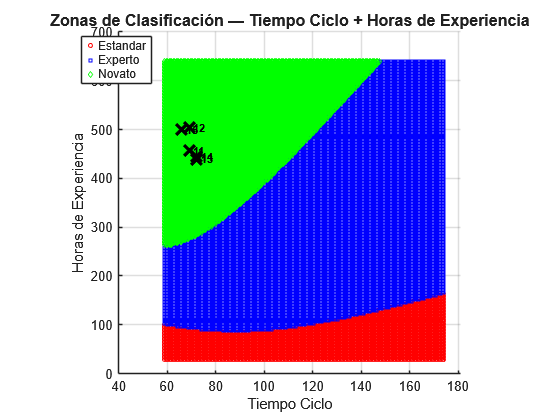

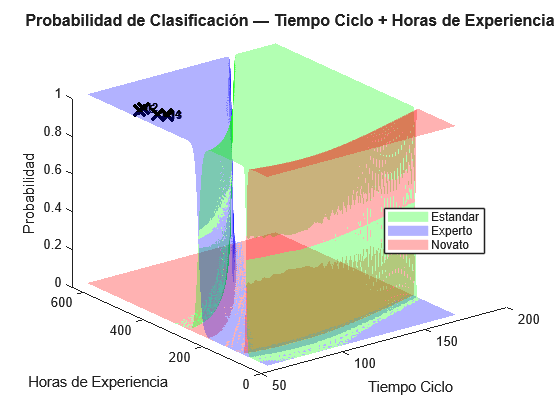

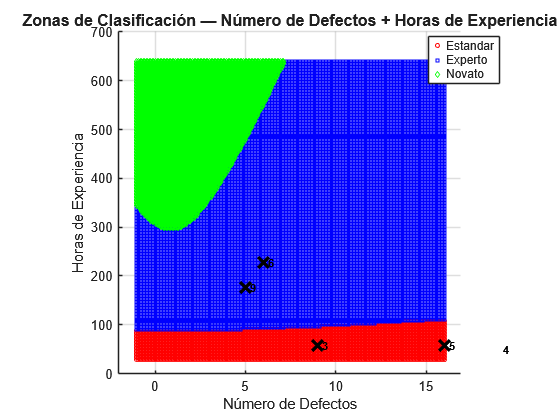

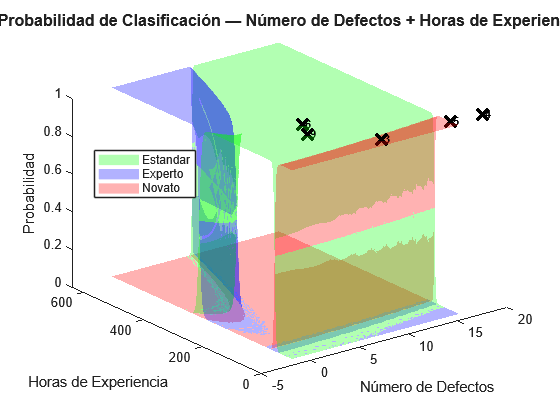

function graficar_clasificaciones_agrupadas( ...
    xx1_TD, xx2_TD, pred_TD, Post_TD, sz_TD, ...
    xx1_TE, xx2_TE, pred_TE, Post_TE, sz_TE, ...
    xx1_DE, xx2_DE, pred_DE, Post_DE, sz_DE, ...
    X_new_completo, probabilidades_finales, variables_usadas, labels)


% Definición de los 3 pares
pares(1).titulo = 'Tiempo Ciclo + Número de Defectos';
pares(1).lbl1   = 'Tiempo Ciclo';
pares(1).lbl2   = 'Número de Defectos';
pares(1).cols   = [1 2];
pares(1).xx1    = xx1_TD;  pares(1).xx2  = xx2_TD;
pares(1).pred   = pred_TD; pares(1).Post = Post_TD; pares(1).sz = sz_TD;

pares(2).titulo = 'Tiempo Ciclo + Horas de Experiencia';
pares(2).lbl1   = 'Tiempo Ciclo';
pares(2).lbl2   = 'Horas de Experiencia';
pares(2).cols   = [1 3];
pares(2).xx1    = xx1_TE;  pares(2).xx2  = xx2_TE;
pares(2).pred   = pred_TE; pares(2).Post = Post_TE; pares(2).sz = sz_TE;

pares(3).titulo = 'Número de Defectos + Horas de Experiencia';
pares(3).lbl1   = 'Número de Defectos';
pares(3).lbl2   = 'Horas de Experiencia';
pares(3).cols   = [2 3];
pares(3).xx1    = xx1_DE;  pares(3).xx2  = xx2_DE;
pares(3).pred   = pred_DE; pares(3).Post = Post_DE; pares(3).sz = sz_DE;

% Offset para que la etiqueta no tape la X
offset_x = 0.02;   % se ajusta automático al rango del eje

for p = 1:3

    % Índices globales (1-15) de los operadores de este par
    idx_par  = find(strcmp(variables_usadas, pares(p).titulo));

    % Coordenadas 2D de esos operadores (ya imputadas en X_new_completo)
    X_par    = X_new_completo(idx_par, pares(p).cols);   % [N x 2]
    prob_par = probabilidades_finales(idx_par);            % [N x 1]

    % Offset proporcional al rango del eje X para no tapar la X
    rango_x  = max(pares(p).xx1(:)) - min(pares(p).xx1(:));
    ox = rango_x * 0.015;

    % FIGURA 2D

    figure('Name', sprintf('2D - %s', pares(p).titulo), 'NumberTitle', 'off');

    gscatter(pares(p).xx1(:), pares(p).xx2(:), pares(p).pred, ...
             'rbg', 'osd', 3);
    hold on

    % Dibujar X para cada operador del par
    for j = 1:length(idx_par)
        scatter(X_par(j,1), X_par(j,2), 130, 'k', 'x', 'LineWidth', 2.5);

        % Etiqueta con número de operador global
        text(X_par(j,1) + ox, X_par(j,2), ...
             sprintf('%d', idx_par(j)), ...
             'FontSize', 8, 'FontWeight', 'bold', 'Color', 'k');
    end

    xlabel(pares(p).lbl1, 'FontSize', 11);
    ylabel(pares(p).lbl2, 'FontSize', 11);
    title(sprintf('Zonas de Clasificación — %s', pares(p).titulo), ...
          'FontSize', 12);
    legend(labels, 'Location', 'best');
    axis square;
    grid on;
    hold off

    % FIGURA 3D
    figure('Name', sprintf('3D - %s', pares(p).titulo), 'NumberTitle', 'off');
    hold on

    surf(pares(p).xx1, pares(p).xx2, ...
         reshape(pares(p).Post(:,1), pares(p).sz), ...
         'FaceColor', 'green', 'EdgeColor', 'none');

    surf(pares(p).xx1, pares(p).xx2, ...
         reshape(pares(p).Post(:,2), pares(p).sz), ...
         'FaceColor', 'blue', 'EdgeColor', 'none');

    surf(pares(p).xx1, pares(p).xx2, ...
         reshape(pares(p).Post(:,3), pares(p).sz), ...
         'FaceColor', 'red', 'EdgeColor', 'none');

    alpha(0.3);

    % Dibujar X en 3D con etiqueta
    for j = 1:length(idx_par)
        scatter3(X_par(j,1), X_par(j,2), prob_par(j), ...
                 150, 'k', 'x', 'LineWidth', 2.5);

        text(X_par(j,1) + ox, X_par(j,2), prob_par(j), ...
             sprintf('%d', idx_par(j)), ...
             'FontSize', 8, 'FontWeight', 'bold', 'Color', 'k');
    end

    xlabel(pares(p).lbl1, 'FontSize', 11);
    ylabel(pares(p).lbl2, 'FontSize', 11);
    zlabel('Probabilidad', 'FontSize', 11);
    legend(labels, 'Location', 'best');
    title(sprintf('Probabilidad de Clasificación — %s', pares(p).titulo), ...
          'FontSize', 12);
    view(3);
    hold off

end
end

graficar_clasificaciones_agrupadas( ...
    xx1_TD, xx2_TD, pred_TD, Post_TD, sz_TD, ...
    xx1_TE, xx2_TE, pred_TE, Post_TE, sz_TE, ...
    xx1_DE, xx2_DE, pred_DE, Post_DE, sz_DE, ...
    X_new_completo, probabilidades_finales, variables_usadas, labels);